7.6 Flow Across Banks of Tubes 

Fundamentals of Heat and Mass Transfer, 8th Edition

Table for C and M values

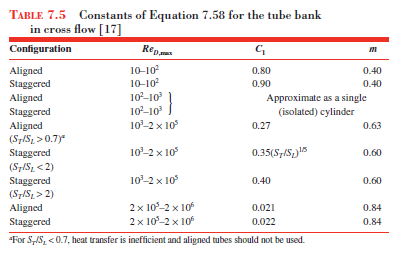

Table for C and M coeffiecents. 

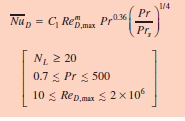

At least 20 tubes(**5 not 20 need correction factor**)

Prandlt number range, Reynolds number range

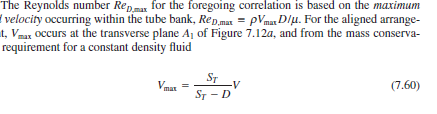

Input vector creation and graphing

AirSpeed = 0:0.1:10;
tempLow = 40+ 273.15;
battTemp = 50+ 273.15;
tempHigh = 42.57 + 273.15;
y = Heatloss(AirSpeed,tempLow,battTemp)
hold on
ylabel('HeatLoss[w]');
plot(AirSpeed,y,'.')
%yyaxis right
%plot(z,AirSpeed,'.')
xlabel('AirSpeed at Entrance [m/s]');
%ylabel('Ploss');
var2 = battTemp-273.15;
var1 = tempHigh-273;
title_string = sprintf("AirSpeed Vs Heatloss at Ambient %.2f C and Battery Temp %.2f",var1,var2)
title(title_string)
grid on;
hold off





function HeatLoss = Heatloss(AirSpeed,tempLow,battTemp)


Basic

%Reynolds Number Calcs
    BattColumns = 5;
    BatteryRows =23;
    
    tempHigh = 40 + 273.15;
    DiameterCells = 18.3/1000; % CHANGE THIS BECAUSE NO GAP




    dynViscosity = py.CoolProp.CoolProp.PropsSI('V', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    densityAir = py.CoolProp.CoolProp.PropsSI('D', 'T', tempLow, 'P|not_imposed', 101325, 'air')
    thermCond = py.CoolProp.CoolProp.PropsSI('L', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    ConstPNum = py.CoolProp.CoolProp.PropsSI('C', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    thermMassAir = py.CoolProp.CoolProp.PropsSI('C', 'T', tempLow, 'P|not_imposed', 101325, 'air')
    KinViscosity = dynViscosity/densityAir;


% Vert vs Horiz Spacing
    St = 24.3/1000;% spacing between columns
    Sl = 34.3/1000;%center spacing in direction of initial airflow
    
    Vmax =  St.*AirSpeed./(St-DiameterCells);

    ReynoldsNumber =  Vmax * DiameterCells / KinViscosity % WILL have to update C1 and M Manually before IF statements. 
    PrandtlAirLow = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    PrandtlAirHigh = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempHigh, 'P|not_imposed', 101325, 'air');

    C1 = 0.35*(St/Sl)^(1/5);
    mVal = 0.6; % Table
    C2 = 0.95; %Table (correction factor for 5)



    NusseltD = C2*C1*ReynoldsNumber.^mVal.*(PrandtlAirLow.^0.36).*(PrandtlAirLow./PrandtlAirHigh).^(0.25);
    Hline = NusseltD*thermCond/DiameterCells;

Adjusted Delta for warming


    insideVarTop = (-pi*DiameterCells*(BattColumns*BatteryRows)*Hline);

    insideVarBot = (densityAir.*AirSpeed.*(BatteryRows)*St*ConstPNum);
    adjDelTso = (battTemp - tempLow) * exp(insideVarTop/insideVarBot);
    To = -((battTemp - tempLow) * exp(insideVarTop/insideVarBot))+battTemp -273.15

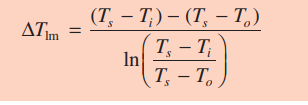

    deltTlm = ((battTemp-tempLow)-(adjDelTso))/(log((battTemp-tempLow)/(adjDelTso)));

    qPrime = (BatteryRows*BattColumns)*(Hline*pi*DiameterCells*deltTlm);%in KW per m
    qPrimeLadjust = qPrime*0.065*6%Temp dissapated
    areaPath = St*BattColumns*0.065;

pressure loss

    Pt = St/DiameterCells;
    Pl = Sl/DiameterCells;
    PTPL = (Pt-1)/(Pl-1);

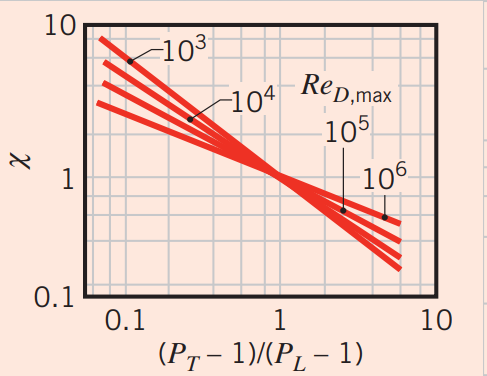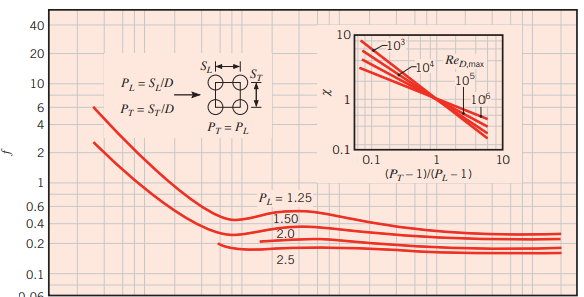

    fancyX = 1.4;
    fricFactor = 0.22;

    deltPLoss = 5.* fancyX .* (densityAir./2.*Vmax.^2) .* fricFactor;

    HeatLoss = qPrimeLadjust;

end